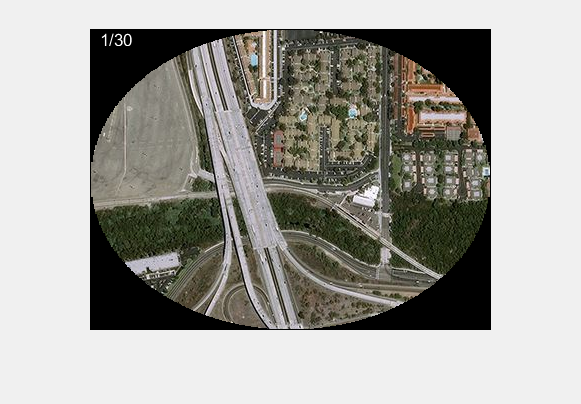

clc
clear all
close all

letter = "B";
directory = "Test Images/Snipped/"+letter+"/";
imagefiles = dir(directory);      
nfiles = length(imagefiles);    % Number of files found

% figure()
counter=1;
for ii=1:nfiles
   currentfilename = imagefiles(ii).name;
   if currentfilename(1)==letter
       currentimage = imread(directory+currentfilename);
       images{counter} = currentimage;
       [~,imageNames{counter},~] = fileparts(currentfilename);
       counter=counter+1;
   end
   % subplot(nfiles-3, 1, ii - 3);
   % imshow(images{ii - 3});
end

neworder = randperm(length(images));
for i=1:length(images)
    images2{i} = images{neworder(i)};
end
images = images2;

% images{1} = imread("Test Images/Snipped/A/A4.jpg");
% images{2} = imread("Test Images/Snipped/A/A7.jpg");
% images{3} = imread("Test Images/Snipped/A/A15.jpg");
% images{4} = imread("Test Images/Snipped/A/A12.jpg");
% images{5} = imread("Test Images/Snipped/A/A18.jpg");

% images{1} = imread("leftoriginal.png")
% images{2} = imread("leftleft.png")

% % right = imread("leftshifted.png");
% figure()
% imshow(images{1})
% imshow(images{2})

fig = figure;
set(gcf,'Visible','on');

out = images{1};
thresh = 0.0005;
speedthresh = 0.005;
speedthresh_trip=false;
valid_thresh = 30;
stitched = zeros(length(images),1);
stitched(1)=1;
length(images);

pltanim(out,stitched);


end_early = false;
default_points = 0.5;
for j=1:length(images)
    disp(j)
    points=default_points;
    finished = false;
    while ~finished
        confidences = zeros(length(images),4);
        speedthresh_trip=false;
        for i=1:length(images)
            if stitched(i)==0
                [final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(out, images{i}, 8, points, true);
                confidences(i,:)=[final_confidence,final_delta_x,final_delta_y, i];
                if confidences(i,1)>=speedthresh
                    disp(confidences(i,1))
                    [out, valid] = merge_images(out, images{i}, round(-confidences(i,2)), round(-confidences(i,3)),valid_thresh/1.5, true);
                    if valid
                        speedthresh_trip=true;
                        stitched(i)=1;
                        points=max(default_points,points-0.5);
                        pltanim(out,stitched);
                    end
                end
            end
        end
        if ~speedthresh_trip
            confidences = sortrows(confidences,1,"descend");
            valid = false;
            for c=1:length(confidences)
                if confidences(c,1)>=thresh
                    disp(confidences(c,1))
                    % [v,ind]=max(confidences(:,1));
                    % disp(v)
                    [out, valid] = merge_images(out, images{confidences(c,4)}, round(-confidences(c,2)), round(-confidences(c,3)),valid_thresh, true);
                    % imwrite(out, "Output/"+letter+"/Run3_Stitch"+sum(stitched)+"_Conf"+round(v*10000)+".png");
                    if valid
                        stitched(confidences(c,4))=1;
                        points=max(default_points,points-0.5);
                        pltanim(out,stitched);
                        break
                    end
                end
            end
            if ~valid
                points=points+0.5
                if points>=3.5
                    finished=true;
                    end_early=true;
                end
            end
        end
    end
    if end_early
        break
    end
end

     1



    0.0080



ans =     1.0066
    1.0050
    1.0084


    0.1070



ans =     1.0887
    1.0876
    1.0884


    0.1070



ans =     0.7258
    0.7251
    0.7256


    0.0061



ans =     1.0066
    1.0050
    1.0084


    0.0061



ans =     0.6710
    0.6700
    0.6722


    0.0014



ans =     2.0442
    1.9707
    2.2367


    0.0014



ans =     1.9922
    1.8545
    1.9456


   6.0496e-04



ans =     2.2134
    2.0859
    2.3035


   6.0496e-04



ans =     2.2091
    2.0941
    2.3381


   6.0496e-04



ans =     2.0849
    1.9316
    2.0514


points = 1

    0.0030



ans =     1.3329
    1.3176
    1.4079


    0.0018



ans =     2.1634
    2.0008
    2.1625


   9.3566e-04



ans =     0.6578
    0.6565
    0.6622


    0.0097



ans =     2.9550
    2.7647
    2.9544


    0.0172



ans =     1.2480
    1.2408
    1.2769


    0.0172



ans =     0.8320
    0.8272
    0.8513


    0.0041



ans =     2.3779
    2.3248
    2.6223


    0.0018



ans =     0.7467
    0.7443
    0.7503


    0.0553



ans =     1.3863
    1.3825
    1.3932


    0.0051



ans =     0.9785
    0.9777
    0.9805


    0.0060



ans =     1.1971
    1.1949
    1.1987


    0.0687



ans =     1.3863
    1.3825
    1.3932


    0.0687



ans =     0.9242
    0.9216
    0.9288


    0.0761



ans =     1.5246
    1.5200
    1.5315


    0.0812



ans =     1.3721
    1.3591
    1.3849


    0.0447



ans =     1.2580
    1.2513
    1.2547


    0.0812



ans =     0.9147
    0.9061
    0.9232


    0.0920



ans =     1.2138
    1.2100
    1.2188


    0.0085



ans =     0.4701
    0.4692
    0.4714


    0.0067



ans =     1.2464
    1.2442
    1.2374


    0.0362



ans =     1.2591
    1.2525
    1.2558


    0.0644



ans =     1.2705
    1.2672
    1.2779


    0.0067



ans =     1.2464
    1.2442
    1.2374


    0.0362



ans =     1.2591
    1.2525
    1.2558


    0.0644



ans =     0.8470
    0.8448
    0.8520


    0.0746



ans =     1.4016
    1.3917
    1.4025


    0.0746



ans =     0.9344
    0.9278
    0.9350


    0.0245



ans =     1.7319
    1.7028
    1.7456


    0.0245



ans =     1.1546
    1.1352
    1.1637


    0.0037



ans =     2.1566
    1.9860
    2.1638


points = 1

    0.0305



ans =     1.6367
    1.6188
    1.6491


    0.0305



ans =     1.0911
    1.0792
    1.0994


   6.8706e-04



ans =     1.1319
    1.1064
    1.1316


   6.8706e-04



ans =     2.0912
    2.0011
    2.2081


points = 1.5000

    0.0357



ans =     1.5877
    1.5693
    1.5967


    0.0357



ans =     1.0585
    1.0462
    1.0645


    0.0017



ans =     1.0105
    0.9978
    1.0084


    0.0017



ans =     0.4375
    0.4359
    0.4430


    0.0367



ans =     1.5877
    1.5693
    1.5967


    0.0826



ans =     1.6329
    1.5999
    1.6762


    0.0513



ans = 3×1
    2.6425
    2.5969
    2.6634


    0.0826



ans = 3×1
    1.0886
    1.0666
    1.1174


    0.0513



ans = 3×1
    1.7617
    1.7313
    1.7756


    0.0367



ans = 3×1
    1.0585
    1.0462
    1.0645


points = 1.5000

    0.0283



ans = 3×1
    1.4203
    1.4076
    1.4305


    0.0893



ans = 3×1
    1.5092
    1.4881
    1.5401


    0.0713



ans = 3×1
    2.4735
    2.4377
    2.4944


    0.0057



ans = 3×1
    3.2498
    3.1259
    3.3738


    0.0893



ans = 3×1
    1.0062
    0.9920
    1.0268


    0.0713



ans = 3×1
    1.6490
    1.6251
    1.6629


    0.0283



ans = 3×1
    0.9468
    0.9384
    0.9537


    0.0983



ans = 3×1
    1.7808
    1.7362
    1.8377


    0.0851



ans = 3×1
    2.6962
    2.6470
    2.7215


    0.0983



ans = 3×1
    1.1872
    1.1574
    1.2251


    0.0851



ans = 3×1
    1.7975
    1.7646
    1.8144


    0.0019



ans = 3×1
    2.1814
    2.1018
    2.3706


   9.2902e-04



ans = 3×1
    2.1241
    2.0157
    2.1882


   6.8254e-04



ans = 3×1
    1.1319
    1.1064
    1.1316


points = 1.5000

    0.0728



ans = 3×1
    1.6329
    1.5999
    1.6762


    0.0580



ans = 3×1
    2.5350
    2.4944
    2.5529


    0.0728



ans = 3×1
    1.0886
    1.0666
    1.1174


    0.0580



ans = 3×1
    1.6900
    1.6629
    1.7019


    0.0014



ans = 3×1
    0.8264
    0.8204
    0.8279


    0.0107



ans = 3×1
    1.3539
    1.3472
    1.3433


    0.0703



ans = 3×1
    1.1111
    1.1056
    1.1227


    0.0464



ans = 3×1
    2.2224
    2.2067
    2.2393


    0.0703



ans = 3×1
    0.7407
    0.7371
    0.7484


    0.0222



ans = 3×1
    2.3636
    2.3451
    2.3658


    0.0222



ans = 3×1
    1.5757
    1.5634
    1.5772


   6.1576e-04



ans = 3×1
    2.1110
    2.0640
    2.3346


points = 1

    0.0222



ans = 3×1
    2.3712
    2.3257
    2.3689


    0.0107



ans = 3×1
    1.8745
    1.8571
    1.8510


    0.0222



ans = 3×1
    1.5808
    1.5505
    1.5793


    0.0107



ans = 3×1
    1.2497
    1.2380
    1.2340


    0.0034



ans = 3×1
    0.9655
    0.9577
    0.9591


    0.0083



ans = 3×1
    1.7394
    1.7317
    1.7482


    0.0362



ans = 3×1
    2.3561
    2.3337
    2.3572


    0.0362



ans = 3×1
    1.5707
    1.5558
    1.5715


    0.0083



ans = 3×1
    1.1596
    1.1545
    1.1654


   6.1576e-04



ans = 3×1
    2.0586
    1.9193
    2.0691


points = 1

    0.0315



ans = 3×1
    2.7328
    2.6754
    2.7815


    0.0246



ans = 3×1
    2.2192
    2.1973
    2.2247


    0.0083



ans = 3×1
    1.8745
    1.8571
    1.8510


    0.0315



ans = 3×1
    1.8218
    1.7836
    1.8544


    0.0246



ans = 3×1
    1.4794
    1.4649
    1.4832


    0.0083



ans = 3×1
    1.2497
    1.2380
    1.2340


    0.0044



ans = 3×1
    1.3626
    1.3570
    1.3850


    0.0017



ans = 3×1
    1.2576
    1.2564
    1.2638


points = 1.5000

    0.0415



ans = 3×1
    2.6562
    2.6078
    2.7014


    0.0427



ans = 3×1
    2.2980
    2.2818
    2.3068


    0.0140



ans = 3×1
    1.8745
    1.8571
    1.8510


    0.0427



ans = 3×1
    1.5320
    1.5212
    1.5379


    0.0415



ans = 3×1
    1.7708
    1.7385
    1.8009


    0.0140



ans = 3×1
    1.2497
    1.2380
    1.2340


    0.0019



ans = 3×1
    1.3626
    1.3570
    1.3850


    0.0015



ans = 3×1
    2.0663
    2.0399
    2.1909


points = 2

    0.0498



ans = 3×1
    2.6772
    2.6293
    2.7255


    0.0436



ans = 3×1
    2.2192
    2.1973
    2.2247


    0.0139



ans = 3×1
    1.8745
    1.8571
    1.8510


    0.0498



ans = 3×1
    1.7848
    1.7529
    1.8170


    0.0436



ans = 3×1
    1.4794
    1.4649
    1.4832


    0.0139



ans = 3×1
    1.2497
    1.2380
    1.2340


    0.0036



ans = 3×1
    1.1784
    1.1755
    1.1975


    0.0031



ans = 3×1
    2.0650
    2.0436
    2.1560


points = 2.5000

sum(stitched)
imageNames(~stitched)
pltanim(out,stitched);
text(10,40,"Done!","Color",[1,1,1]);
imwrite(out, "Output/"+letter+"/"+rand()+".png");

function [] = pltanim(out, stitched)
        imshow(out);
        text(10,10,""+sum(stitched)+"/"+length(stitched),"Color",[1,1,1]);
        drawnow();
end